Όταν θέλουμε να εκπαιδεύσουμε ένα μοντέλο μηχανικής μάθησης συνήθως έχουμε περιορισμένο αριθμό/ογκο δεδομένων. Αν χρησιμοποιήσουμε όλα τα δεδομένα μας για την εκπαίδευση του μοντέλου τότε υπάρχει πάντα ο κίνδυνος της **υπερπροσαρμογής(overfitting)** του μοντέλου μας στα δεδομένα με αποτέλεσμα ενώ το σφάλμα θα είναι χαμηλό αν έρθει ένα **νέο** δεδομένο που **δεν είναι από την ίδια** κατανομή με τα δεδομένα εκπαίδευσης τότε η πρόβλεψη/εκτίμηση για αυτό το σημείο μπορεί να μην ανταποκρίνεται στην πραγματικότητα, δηλαδή το μοντέλο μας δεν έχει προσεγγίσει την **συνάρτηση**/**κατανομή** που παράγει τα δεδομένα αλλά έχει υπερπροσαρμοστεί στα δεδομένα εκπαίδευσης όπως φαίνεται στην παρακάτω εικόνα από το site της Mathworks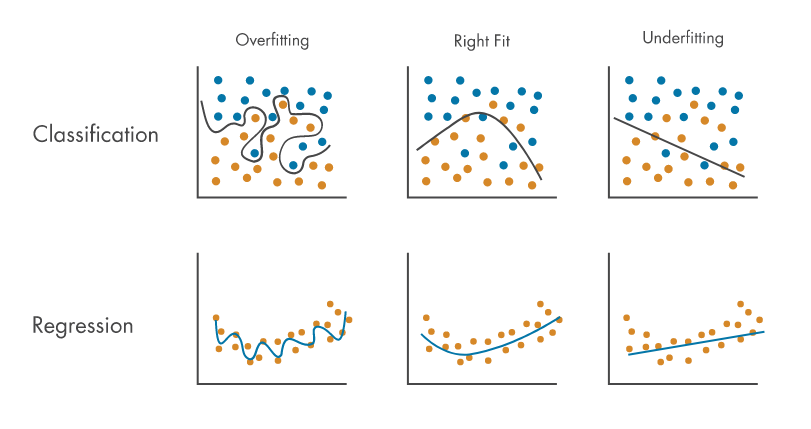

Για να εντοπίσουμε αλλά και να αντιμετωπίσουμε το παραπάνω πρόβλημα συνήθως χωρίζουμε τα δεδομένα μας σε δύο υποσύνολα το **Train set** και το **Test set**. Όπως υποδεικνύουν και τα ονόματα τους το πρώτο(**Train** set) χρησιμοποιείται κατά τη διάρκεια της εκπαίδευσης του μοντέλου ενώ το δεύτερο(**Test** set) χρησιμοποιείται για τον έλεγχο του μοντέλου σε δεδομένα που δεν έχει δει **καθόλου κατά τη διάρκεια της εκπαίδευσης του! **Όταν ο όγκος των δεδομένων μας είναι μεγάλος συνήθως χωρίζουμε τα δεδομένα μας 90%-10%, δηλαδή 90% των δεδομένων για training και 10% για testing. Τα όρια αυτά είναι εμπειρικά και μεταβάλλονται ανάλογα με το πρόβλημα, το μοντέλο, τις απαιτήσεις για ακρίβεια και προφανώς τον όγκο των δεδομένων. Τέλος, η παραπάνω διαδικασία μπορεί να μας βοηθήσει να αντωπίσουμε αν μας έχουν ξεφύγει τυχόν σημεία επιρροής κατά τη διαδικασία του καθαρισμού των δεδομένων. Ένα τέτοιο παράδειγμα φαίνεται παρακάτω!

x = -3:0.1:3;
noise = 0.2*rand(1,size(x,2))

noise =     0.1629    0.1812    0.0254    0.1827    0.1265    0.0195    0.0557    0.1094    0.1915    0.1930    0.0315    0.1941    0.1914    0.0971    0.1601    0.0284    0.0844    0.1831    0.1584    0.1919    0.1311    0.0071    0.1698    0.1868    0.1357    0.1515    0.1486    0.0784    0.1311    0.0342    0.1412    0.0064    0.0554    0.0092    0.0194    0.1647    0.1390    0.0634    0.1900    0.0069    0.0877    0.0763    0.1531    0.1590    0.0374    0.0980    0.0891    0.1293    0.1419    0.1509


t = x.^2 - 3*x  +2 + noise;

t(1,12) = t(1,12) +4 ;
t(1,30) = t(1,30) -4 ;

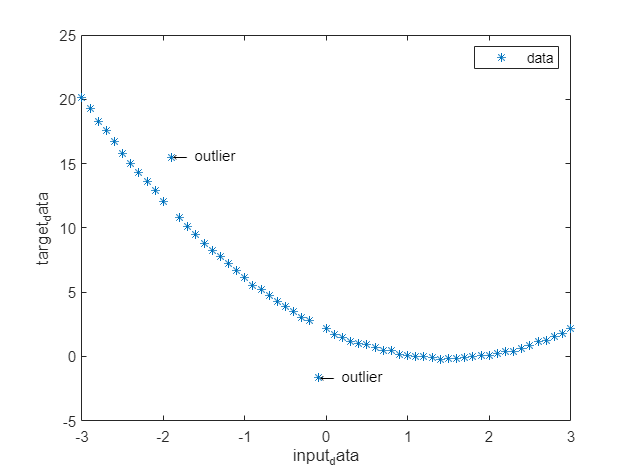

figure
plot(x,t(1,:), '*')

txt = '\leftarrow outlier';
text(x(1,12),t(1,12),txt)

txt2 = '\leftarrow outlier';
text(x(1,30),t(1,30),txt2)

legend('data')
xlabel('input_data')
ylabel('target_data')

net = fitnet(10); 
net = configure(net, x(1,1:56), t(1,1:56))

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 31
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input

view(net)

[net, tr] = train(net, x(:,1:56), t(1,1:56));

preds = net(x(:,1:56)) 

preds =    20.2344   19.4345   18.4170   17.5685   16.9330   16.2228   15.2266   14.1450   13.3531   12.8768   12.4912   11.9516   11.1118   10.1065    9.2766    8.7505    8.3829    7.9450    7.2644    6.4425    5.7975    5.4193    5.1749    4.9240    4.5683    4.0548    3.4050    2.7293    2.1591    1.7571    1.5078    1.3641    1.2812    1.2232    1.1545    1.0270    0.7996    0.5235    0.3195    0.2136    0.1568    0.1020    0.0228   -0.0699   -0.1390   -0.1711   -0.1738   -0.1478   -0.0813    0.0294


Το μοντέλο φαίνεται να προσαρμόζεται σχετικά καλά προς μέτρια στα δεδομένα εκπαίδευσης. Αν αυτό ήταν όλο το σετ των δεδομένων μας θα λέγαμε πως το μοντέλο μας είνα σχετικά καλό.

figure
p1 = plot(preds,'r+')

p1 =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '+'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56]
              YData: [20.2344 19.4345 18.4170 17.5685 16.9330 16.2228 15.2266 14.1450 13.3531 12.8768 12.4912 11.9516 11.1118 10.1065 9.2766 8.7505 8.3829 7.9450 7.2644 6.4425 5.7975 5.4193 5.1749 4.9240 4.5683 4.0548 3.4050 2.7293 2.1591 1.7571 … ]
              ZData: [1×0 double]

  Show all properties


xlabel("input data")
ylabel("True Value")
grid on
hold on
hold on
p2 = plot(t(1,1:56),'go')

p2 =   Line with properties:

              Color: [0 1 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56]
              YData: [20.1629 19.2912 18.2654 17.5727 16.6865 15.7695 15.0157 14.2994 13.6315 12.9030 12.0315 15.5041 10.8314 10.0871 9.5201 8.7784 8.2444 7.7731 7.1984 6.7019 6.1311 5.5171 5.2098 4.7768 4.2957 3.9015 3.5086 3.0684 2.7711 -1.6558 … ]
              ZData: [1×0 double]

  Show all properties


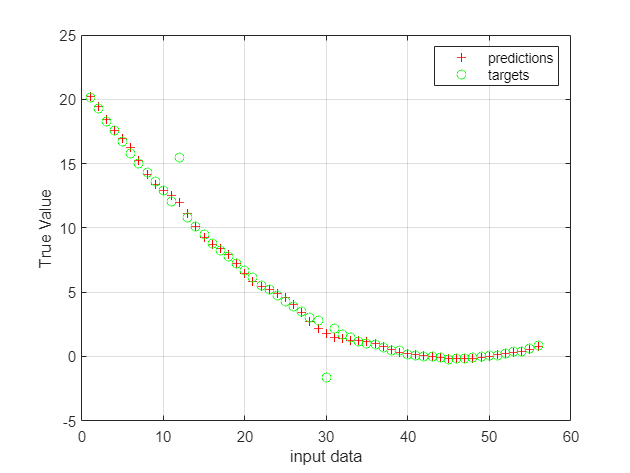

legend(["predictions", "targets"])

Δημιουργούμε προβλέψεις και για τα υπόλοιπα δεδομένα

test_preds = net(x(:,56:61))

test_preds =     0.7966    1.0208    1.1594    1.2234    1.2489    1.2585


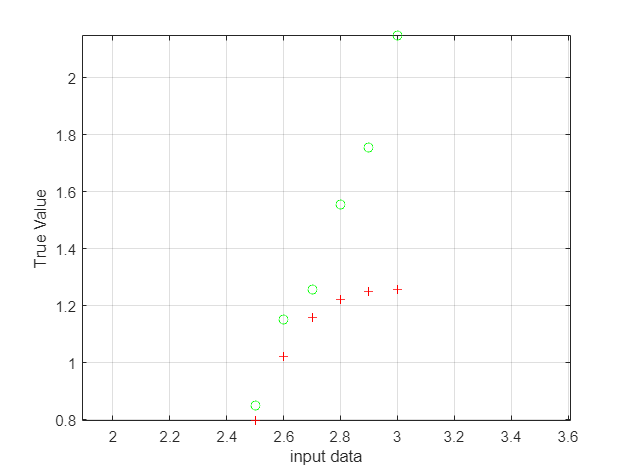

figure
plot(x(:,56:61),test_preds,'r+')
grid on
hold on
hold on
axis equal
plot(x(:,56:61),t(1,56:61),'go')
xlabel("input data")
ylabel("True Value")